# Project

Author: Mahmud Suhaimi Ibrahim

Date: 04/21/2025

clc; clear; close all;

### Description:

After successfully completing ME8287, your employer has promoted you to be the company’s electric machine designer. On your first day of work in your new position, you are asked to complete the magnetic design for a new electric machine that the company is developing for the wastewater aeration equipment market. You are told that the design should have a rated speed of 10,000 RPM, have a rated power of 50 kW, have an electric frequency under 600 Hz, have three phases, use surface mounted permanent magnets on the rotor, and use forced air cooling. You need to determine the number of slots, poles, the winding layout, and various dimensions of the machine. Your objectives are to minimize the design cost, losses, and torque ripple. Customers will only buy your design if it has an efficiency over 90% and a torque ripple less than 50% (and your manager is hoping that with the new skills you learned in ME8287 that you can create a design with even better performance).

### Question 1

Propose a number of slots and poles that you wish to use in your design which satisfies the electric frequency and symmetry requirements. Submit this in Canvas as your first deliverable in the form of a ranked list of 3 slot / pole combinations you are interested in. 

My selection:


$$Q=12, p=2$$


Extra notes:

I am calculating the winding factor here for future reference.

v = 1:7;

p = 2; Q = 12; m = 3; q = Q/(2*p*m); yQ = m*q;
y = yQ;
slots = [1,4,7,10];
coil_config = [1,-1,1,-1];

[K_dv,K_pv,K_wv] = winding_factor(v,p,Q,m,y,slots,coil_config);

disp('K_wv:')

K_wv:


disp(K_wv)

    1.0000    0.0000    1.0000    0.0000    1.0000    0.0000    1.0000



function [K_dv,K_pv,K_wv] = winding_factor(v,p,Q,m,y,slots,coil_config)
    t = gcd(Q,p);
    
    Q_prime = Q/t;
    p_prime = p/t;
    
    Z = Q_prime/m;
    
    alpha_c = 2*pi/Q;
    alpha_u = p*alpha_c;
    
    gamma = y*alpha_c;
    
    %% Distribution Factor
    alpha_i = alpha_c*(slots-1);
    
    Z_c = length(alpha_i);
    
    K_dv = NaN(size(v));
    
    for i = 1:length(v)
        K_dv(i) = abs(sum(exp(-v(i)*p*1i*alpha_i).*coil_config))/Z_c;
    end

    
    %% Pitch Factor
    K_pv = NaN(size(v));
    
    for i = 1:length(v)
        K_pv(i) = abs(sin(v(i).*p*(gamma)/2));
    end
    
    %% Winding Factor
    K_wv = K_dv.*K_pv;

end

### Question 2

Perform a winding layout. Make this a double layer winding. Provide a winding schematic for your design that shows the connections of phase u. Select an appropriate winding fill factor for your winding: $k_{cu}$. Write an expression for $\alpha_{w}$ in terms of the mechanical rotor angle that should be used to create the maximum torque per ampere of current if the winding currents are given by $I_u=\hat{I}\cos{\alpha_w}$, $I_v = \hat{I}\cos{(\alpha_w-\frac{2\pi}{3})}$, $I_w=\hat{I}\cos{(\alpha_w-\frac{4\pi}{3})}$. Assume that slot 1 is aligned with $\alpha=0$.

Answer:


$$Q=12, p=2, m=3$$


Slots per pole per phase:


$$q=\frac{Q}{2pm}=\frac{12}{2(2)(3)}=1$$


Full pitch coil span:

$y_Q = mq = (3)(1)=3$, I will be using the full pitch coil span $y=y_Q$.

Coils per phase:


$$z_c = \frac{Q}{m} = \frac{12}{3} = 4$$


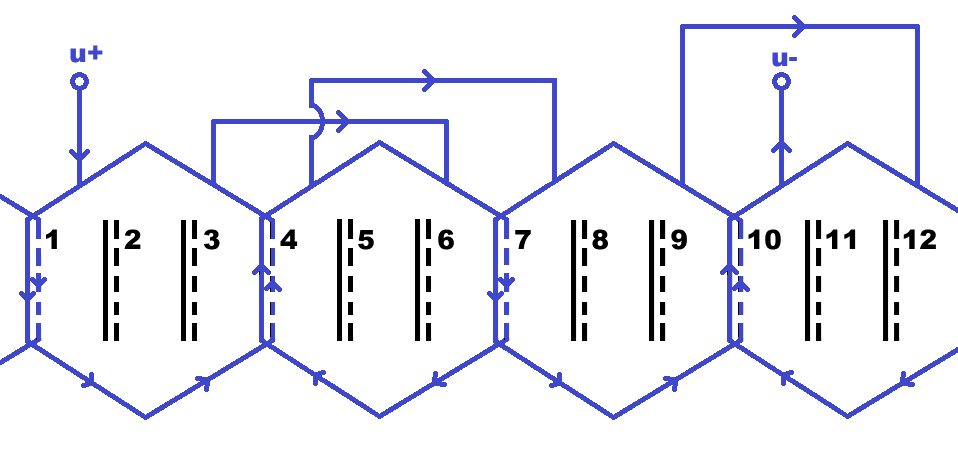

**Figure 1 **Winding schematic for my design that shows the connections of phase u.

Winding fill factor:

$k_{cu}=0.4$, because it is a distributed double-layer winding.

Largest current linkage will happen when $\alpha = 45^{\circ}$, so $\phi=90^{\circ}$.


$$\theta_m + 45 = \frac{\alpha_w+90}{2}$$


Expression for $\alpha_{w}$ in terms of the mechanical rotor angle:


$$\alpha_w = 2\cdot \theta_m$$


MATLAB Code Results:

disp(['Slots per pole per phase, q = ', num2str(q)])

Slots per pole per phase, q = 1


disp(['Full pitch coil span, y_Q = ', num2str(yQ)])

Full pitch coil span, y_Q = 3


### Question 3

Finish the incomplete components of “Dependent and fixed variables,” “Allowable free variable range,” and “Constraints.” Do this by providing the following expressions:

#### Part (a)

Number of turns in a coil $z_Q$.

Answer:

Since I am using 18 AWG wire, which has a  and I chose my $k_{cu} = 0.4$, I can say that the number of turns in a coil for a double layer winding has to be


$$z_Q = \frac{k_{cu}S_u}{2\cdot S_c}$$


where $S_u = \frac{1}{2}\alpha_c(r_{o}^2-r_{i}^2)-w_{st}d_{st}$.

$r_o = r_s - d_{sy}$, and $r_i = r_o - d_{st}=r_s-d_{sy}-d_{st}$. I can substitute these to get:


$$S_u = \frac{1}{2}\alpha_c((r_s-d_{sy})^2-(r_s-d_{sy}-d_{st})^2)-w_{st}d_{st}$$



$$S_u = \frac{1}{2}\alpha_c(2(r_s-d_{sy})d_{st}-d_{st}^2)-w_{st}d_{st}$$



$$S_u = (\alpha_c(r_s-d_{sy})-w_{st})d_{st}-\frac{1}{2}\alpha_cd_{st}^2$$


Or, we can think of it from the rotor's perspective, where $r_i = r + \frac{\delta}{2} + d_{sp}$ ** and $r_o = r_i + d_{st}$. In that case,


$$S_u = \frac{1}{2}\alpha_c d_{st}^2 + (\alpha_cr_i - w_{st})d_{st}$$


In theory, they should be the same thing, because $r+\frac{\delta}{2}+d_{sp} = r_s - d_{sy} - d_{st}$.

**Note that:

- $r$ is the airgap radius.

- $\delta$ is the airgap length.

Extra notes:

#### Part (b)

Determine appropriate range for: $\alpha_{st}$

Thinking about this, the largest physically possible $\alpha_{st} = \frac{360}{Q} = \frac{360}{12} = 30^{\circ}=\frac{\pi}{6}~rad$

However, there are a few constraints that need to be considered. I am using the *checkToothTip *to find the minimum. To allow for the coils to actually physically go into the slots,  $\left( \frac{\pi}{6}-\alpha_{st}\right)\cdot r_{si} > d_c$, where $d_c$ is the diameter of one turn of a coil and is equal to $1.024~mm$. $r_{si}$ is the sum of the rotor radius and the airgap length, which I have shown later is $r_{si} = 91.5~mm$. Therefore $\left( \frac{\pi}{6}-\alpha_{st}\right) > 0.0113 \rightarrow \alpha_{st}<0.5123~rad = 29.35^{\circ}$. Just to keep it safe and put in more than just one turn at a time, I will take the maximum angle to be $28^{\circ}$.

The final appropriate range for $\alpha_{st}$ is:


$$1.8^{\circ}<\alpha_{st}<28^{\circ}$$


However, not every $\alpha_{st}$ will work for every design. So the check will need to be used when actually selecting an $\alpha_{st}$.

MATLAB Code Results:

%% Fixed variables
dso = 2;           %[mm]
dsp = 4;           %[mm]
rs = 180;          %[mm]

%% Allowable free range variables
delta_array = 1:1:5;
wst_array = 5:1:100;
dst_array = 5:1:100;
dsy_array = 5:1:50;

alpha_st_grid = deg2rad(0:0.1:30);

index_ast = NaN(length(alpha_st_grid), length(wst_array), length(dst_array), length(dsy_array));

max_ast = NaN(length(wst_array), length(dst_array), length(dsy_array));
min_ast = NaN(length(wst_array), length(dst_array), length(dsy_array));

for j2 = 1:length(wst_array)
    for k2 = 1:length(dst_array)
        for l2 = 1:length(dsy_array)  
            for m2 = 1:length(alpha_st_grid)
            index_ast(m2,j2,k2,l2) = checkToothTip(rs, dso, dsp, dst_array(k2), wst_array(j2), dsy_array(l2), alpha_st_grid(m2));
            end
            if any(index_ast(:,j2,k2,l2) == 0)
                accept_ast = alpha_st_grid(~logical(index_ast(:,j2,k2,l2)));
            end
            max_ast(j2,k2,l2) = max(accept_ast);
            min_ast(j2,k2,l2) = min(accept_ast);
        end
    end
end

min_ast_final = rad2deg(min(min_ast(:)));
max_ast_final = rad2deg(max(max_ast(:)));

disp(['Range of acceptable alpha_st: ', num2str(min_ast_final),' < alpha_st < ', num2str(max_ast_final)]);

Range of acceptable alpha_st: 1.8 < alpha_st < 30


#### Part (c)

Constraint equation to ensure acceptable tooth tip shape. Hint: This should be in terms of free variables $w_{st}$ and $\alpha_{st}$ and may include other free and dependent variables.

*Note: I am confused by this question! The code is provided in the folder.*


$$g(\alpha_{st}) = \frac{w_{st}}{2} -  \left( r_s - d_{sy} - d_{st} - d_{sp} \right) \cdot \sin\left( \frac{\alpha_{st}}{2} \right) \leq 0$$


### Question 4

Create an expression for active material cost (rotor and stator steel, rotor magnets, stator copper) in terms of the free and dependent variables that you will use to evaluate this objective. For the copper, please determine the length of magnet wire based on the same expression for length that we used for loss calculations.

### Question 5

Perform an initial analytic design of your motor to determine a set of values for the free variables that satisfy the allowable variable range and the constraint. Indicate the following information:

#### Part (a)

Selected magnetic loading, electric loading, and rotor volume.

Answer:

Torque rating of the motor is:


$$Rated~Torque = \frac{Rated~Power}{Rated~Speed}=\frac{50000}{10000\cdot \frac{2\pi}{60}} = 47.7465 ~Nm$$


From Table 6.4 of the textbook:

I chose reasonable values that are within the allowable range. This will give a good balance of tangential stress and rotor volume to make up the torque.


$$\hat{B_{\delta}} = 0.9~T$$



$$\hat{A}_{rms} = 55~kA/m$$



$$V_r = \frac{Rated~Torque}{\hat{B}\cdot \hat{A}} = \frac{47.7465}{1\cdot 55\sqrt{2} \times 10^3 } = 6.8206\times 10^{-4}~m^3$$


MATLAB Code Results:

% Finding the Rated Torque
P_rated = 50e3;
Omega_rated = 10e3 * (2*pi)/60;

ratedTorque = P_rated/Omega_rated;
disp(['The rated torque is: ', num2str(ratedTorque)])

The rated torque is: 47.7465


% Volume of the rotor
B_delta_hat = 0.9; % [T]
A_rms = 55e3; % [A/m]
A_hat = A_rms * sqrt(2); % [A/m]

Vr = ratedTorque/(B_delta_hat*A_hat);
disp(['Volume of the rotor, V_r = ', num2str(Vr),' m^3']);

Volume of the rotor, V_r = 0.00068206 m^3


#### **Part (b)**

Number of turns in a coil.

Answer:

Current density of the conductor is $5~\frac{A_{rms}}{mm^2}$, and I am using an 18 AWG wire, so $S_c = 0.8231~mm^2$


$$\hat{I}_{rms} = 5\cdot 0.8231 =  4.12~A_{rms}$$



$$\hat{A} = \frac{3}{\pi}\cdot \frac{z_Q}{r} \cdot \hat{I}\cdot z_c \cdot \hat{K}_{w,1}$$


$z_Q = \frac{\pi\cdot \hat{A}_{rms}\cdot r}{3 \cdot \hat{I}_{rms}\cdot z_c\cdot \hat{K}_{w,1}}$, where $r$ is the airgap radius that needs to be set.

The surface speed of the rotor has to be less than $175~m/s$, so the rotor radius has to be less than 


$$r_{rotor} = \frac{v}{\Omega_r}<\frac{175}{10000\cdot\frac{2\pi}{60}} = 0.1671~m = 167.1~mm$$


I am choosing $r_{rotor} = 90~mm$, I think this is a good choice to keep losses down.

Also, I am picking $\delta = 1.5~mm$, I believe this is a good compromise fo torque ripple, efficiency and cost.


$$\therefore r = r_{rotor}+\frac{\delta}{2} = 90 + \frac{1.5}{2} = 90.75~mm$$


Now, I can find the number of turns, 


$$z_Q = \lfloor{\frac{\pi\times 55\times 10^3\times 90.75\times 10^{-3}}{3 \times 4.12\times 4\times 1}}\rfloor = 387~turns$$


MATLAB Code Results:

%% Slot fill factor
kcu = 0.4;         

%% Choice of wire
coil_AWG = 18;
dwire=0.324861*0.0254*exp(-0.115942*coil_AWG); % wire diameter in meters as a function of AWG
Sc = 0.25*pi*dwire^2; % [m^2]

disp(['Cross-sectional area of conductor, S_c = ', num2str(Sc),' m^2']);

Cross-sectional area of conductor, S_c = 8.2309e-07 m^2


% Peak RMS current going through the wire
J = 5; % [A_rms/mm^2]
iRMS = 5*Sc*1e6; % [A_rms]
iHat = iRMS * sqrt(2);

disp(['RMS Current going through the wire, I_rms = ', num2str(iRMS),' A_rms']);

RMS Current going through the wire, I_rms = 4.1154 A_rms


% My choices
r_rotor = 110; % [mm]
delta = 1.5; % [mm]
r = r_rotor + delta/2; % [mm]

% Number of turns 
zC = 4; % Number of coils in series
Kw1 = K_wv(1);
zQ_analytic = floor((pi*A_rms*r*1e-3)/(3*iRMS*zC*Kw1));
disp(['Number of turns per coil, zQ = ', num2str(zQ_analytic),' turns']);

Number of turns per coil, zQ = 387 turns


Extra notes (You may ignore):

I found the bounds of the slot area and consequently the upper and lower bounds of the number of turns. MATLAB code is attached for reference.

$S_{u,upper}= 6044.9847~mm^2$, $S_{u, lower} = 0~mm^2$

I am flooring to get the closest integer. This makes sure that my slot fill factor will not be higher than my estimate. Just my personal decision. Finally, the range of acceptable turns per coil is:

$0<z_Q<1468$ turns.

Interestingly and predictably, the max number of turns can be fitted when,


$$w_{st} = 5~mm, d_{st}=100~mm, d_{sy} = 5~mm$$


Just thinking about it, this will give the largest slot area.

MATLAB Code Results:

[wst_grid, dst_grid, dsy_grid] = ndgrid(wst_array, dst_array, dsy_array); 

%% Angle between slots
alpha_c = (2*pi)/Q; % [rad]

%% Slot area
% Calculation done in mm, so output will be mm^2.
% Su_grid = alpha_c*(rs-dsy_grid-wst_grid).*dst_grid - 0.5*alpha_c*dst_grid.^2;
ri_grid = rs - dsy_grid - dst_grid;
Su_grid = 0.5*alpha_c*dst_grid.^2 + (alpha_c*ri_grid-wst_grid).*dst_grid;
% Upper bound
[Su_upper, position1] = max(Su_grid(:)); 
[j1,k1,l1] = ind2sub(size(Su_grid),position1);
% Lower bound
Su_lower = min(Su_grid(:));
Su_lower = (Su_lower > 0)*Su_lower; % The minimum can be zero, that is why this line.

%% Turns per coil
% Upper bound
zQ_upper = floor((kcu*Su_upper*1e-6)/(2*Sc));
% Lower bound
zQ_lower = floor((kcu*Su_lower*1e-6)/(2*Sc));

disp(['Upper bound of stator slot area, S_u = ', num2str(Su_upper), ' mm^2. ', ...
    'The corresponding number of turns per coil, zQ = ', num2str(zQ_upper)])

Upper bound of stator slot area, S_u = 6044.9847 mm^2. The corresponding number of turns per coil, zQ = 1468


disp(['Lower bound of stator slot area, S_u = ', num2str(Su_lower), ' mm^2. ', ...
    'The corresponding number of turns per coil, zQ = ', num2str(zQ_lower)])

Lower bound of stator slot area, S_u = 0 mm^2. The corresponding number of turns per coil, zQ = 0


#### Part (c)

The maximum field in the stator teeth

Answer:

Referring to Table 6.2 from the book, I am selecting $\hat{B}_T = 1.6~T$.

#### Part (d)

The maximum field in the stator yoke

Answer:

Referring to Table 6.2 from the book, I am selecting $\hat{B}_y = 1.3~T$.

#### Part (e)

All dimensions of the machine cross-section (free variables and the dependent variables)

Recap:

Just a recap of the dimensions already available or calculated:

*Given dependent and fixed variables:*

- 
$$d_{so} = 2~mm$$


- 
$$d_{sp} = 4~mm$$


- 
$$\alpha_m = \frac{180}{p} = \frac{180}{2} = 90^{\circ}$$


- 
$$r_s = 180~mm$$


*Free variables:*

- 
$$\delta = 1.5~mm$$


*Calculated variables:*

- 
$$r_{rotor} = 110~mm$$


- 
$$l = \frac{V_r}{pi\cdot r_{rotor}^2}=\frac{6.1385\times 10^{-4}}{\pi\times (110\times 10^{-3})^2} = 17.94~mm$$


Answer:

There are a few variables that need to be calculated, I will find them in the same way as shown in Lecture 19.

*Tooth width:*

- 
$$w_{st} = \frac{\alpha_c\cdot r\cdot \hat{B}_{\delta}}{\hat{B}_T} = 32.62~mm$$


*Stator yoke thickness:*

Assuming $B_{\delta} = \hat{B}_{\delta}\cos{(p\alpha)} = 1\cdot \cos(2\alpha)~[T]$

- 
$$d_{sy} = \frac{r\int_{-\frac{\pi}{2p}}^{\frac{\pi}{2p}} B_{\delta}(\alpha) \,d\alpha}{2\hat{B}_y} = \frac{110.75\times \int_{-\frac{\pi}{4}}^{\frac{\pi}{4}}\cos{2\alpha  \,d\alpha}}{2\times 1.3} = 38.34~mm$$


*Slot dimensions:*

Picking a value for $\alpha_{st}$ based on the wire thickness and the inner radius of the stator. Of course I am also taking into account the allowable range of $1.8^{\circ} < \alpha_{st} < 30^{\circ}$.

- 
$$\alpha_{st} =  25^{\circ}$$


For $d_{st}$, I need to calculate the slot area available first, which is:

- 
$$k_{cu} = 0.4$$


- 
$$S_u = \frac{z_Q\cdot S_c}{2k_{cu}}=\frac{387\times 0.82309}{2\times 0.4} = 398.17~mm^2$$


Now, using the expression I derived in Question 3,

- 
$$\frac{1}{2}\alpha_c d_{st}^2 + (\alpha_cr_i - w_{st})d_{st}-S_u = 0$$


- 
$$d_{st} = 12.76~mm$$


*Rotor dimensions:*

Magnet parameters: (I will be using the nominal values)

- 
$$B_r = 1.27~T$$


- 
$$\mu_r = \frac{B_r}{\mu_0\cdot H_c} = \frac{1.27}{1.2566\times 10^{-6} \times 951\times 10^3} \approx 1.06$$


Magnet thickness, (equation derived in Homework 3 using a Magenetic equivalent circuit). 

- 
$$d_m = \frac{\hat{B}_{\delta}\cdot \mu_r \cdot \delta}{B_r - \hat{B}_{\delta}} = 3.87~mm$$


The rotor core radius can now be calculated by subtracting the magnet thickness from the rotor radius

- 
$$d_{ri} = r_{rotor} - dm = 90 - 3.87 = 106.13~mm$$


*Stator yoke adjustment:*

The problem is that the stator outer radius after calculating all the dimensions is less than $180~mm$.

- 
$$r_{s,analytic} = 166.6~mm$$


To deal with this issue, rather than changing the other dimensions, I will increases the stator yoke thickness to make up the difference.

- 
$$d_{sy,new} = d_{sy} + (r_s - r_{s,analytic}) = 51.74~mm$$


So now I can say that (with some rounding error),

- 
$$d_{ri}+d_m+\delta+d_{sp}+d_{st}+d_{sy} = r_s = 180~mm$$


MATLAB Code Results:

% Calculating the axial length
l = Vr/(pi*(r_rotor*1e-3)^2); % [m]
l_mm = l*1e3; % [mm]

disp(['Axial length of the machine, l = ', num2str(l_mm), ' mm'])

Axial length of the machine, l = 17.9426 mm


% Newly defined parameters
B_T = 1.6; % [T] Max field for tooth
B_y = 1.3; % [T] Max field for stator yoke
B_r = 1.27; % [T] Magnet field
mu_r = 1.06; % Magnet relative permeability
alpha_st = 25; % [degree]
alpha_m = 180/p; % [degree]

disp(['Tooth tip angle, alpha_st = ', num2str(alpha_st), ' degrees']);

Tooth tip angle, alpha_st = 25 degrees


% Tooth width
wst = (alpha_c*r*B_delta_hat)/(B_T); % [mm]

disp(['Tooth width, wst = ', num2str(wst), ' mm']);

Tooth width, wst = 32.6186 mm


% The slot area
Su = (zQ_analytic*Sc*1e6)/(2*kcu);

disp(['Slot area available, Su = ', num2str(Su), ' mm^2']);

Slot area available, Su = 398.1681 mm^2


% The stator yoke thickness
B_delta_fun = @(alpha) B_delta_hat*cos(p*alpha);

dsy = (r*integral(B_delta_fun,-pi/(2*p),pi/(2*p)))/(2*B_y);

disp(['Stator yoke thickness, dsy = ', num2str(dsy), ' mm']);

Stator yoke thickness, dsy = 38.3365 mm


% The slot dst
% Solving the quadratic equation using roots(). I think this is the best way.
ri = r + delta/2 + dsp;
dst_array = roots([0.5*alpha_c, alpha_c*ri-wst, -Su]);

% dst_array = roots([-0.5*alpha_c, alpha_c*(rs-dsy)-wst, -Su]);
dst = dst_array(dst_array<100 & dst_array>5);
disp(['Slot depth, dst = ', num2str(dst), ' mm']);

Slot depth, dst = 12.7625 mm


% Magnet thickness
dm = (B_delta_hat*mu_r*delta)/(B_r-B_delta_hat);
disp(['Magnet thickness, dm = ', num2str(dm), ' mm']);

Magnet thickness, dm = 3.8676 mm


% Rotor core depth
rsi = rs - dsy - dst - dsp;
dri = r_rotor - dm;
disp(['Rotor core radius, dri = ', num2str(dri), ' mm']);

Rotor core radius, dri = 106.1324 mm


% Checking the outer radius
rs_analytic = dri+dm+delta+dsp+dst+dsy;
disp(['Stator radius from calculation, rs_analytic = ', num2str(rs_analytic), ' mm']);

Stator radius from calculation, rs_analytic = 166.599 mm


% New stator yoke thickness
dsy = dsy + (rs-rs_analytic);
disp(['Modified stator yoke thickness, dsy = ', num2str(dsy), ' mm']);

Modified stator yoke thickness, dsy = 51.7375 mm


% Array to use as initial population
ast = alpha_st;
popArray = [dm, delta, dsy, dst, wst, ast];

disp('Population Array:')

Population Array:


disp(popArray)

    3.8676    1.5000   51.7375   12.7625   32.6186   25.0000



return

### **Question 6 (Extra Credit)**

Modify $evaluateDesign$ from HW3 by having it determine the required axial length to achieve a specified rated torque. Do this by performing the complete FEMM analysis of your machine with an axial length of 1mm, extract the field and torque values at each rotor location (just like you did in HW3, but now the length is 1mm), and then calculate the length required to obtain the rated torque. Use this newly calculated length for the loss calculations. The function should have the following function signature (the only differences are ratedTorque in Nm and the returned length in mm): *function [designEval, length] = evaluateDesign(materials, dimensions, p, winding, settings, ratedTorque)* I am providing you with an evaluateDesign.p file that has already implemented this which you can use in your optimization. You will receive extra credit if you create your own working evaluateDesign.m function.

% Working progress

### Question 7

Create a MATLAB function evaluateConstraints that will be called by MATLAB’s gamultiobj. This function is responsible for evaluating the design constraints. In addition to the constraints that I have indicated above, I am providing you with a MATLAB function $checkToothTip$ which will indicate whether your free variables will yield valid tooth-tip geometry. The function returns 0 if the geometry is valid and 1 if the geometry is invalid. Use this function inside evaluateConstraints to constrain the optimization to valid geometry.

% Done

### Question 8

Create a MATLAB function evaluateObjectives that will be called by MATLAB’s gamultiobj. This function will receive the optimization algorithm’s free variables as its arguments, formulate the arguments for evaluateDesign (calculate the dependent variables), call evaluateDesign, and then convert the returned values of designEval into the objectives that this function will return. This function will implement a lot of the functionality of $testDesign1.m$ from Homework 3. To determine the appropriate $settings.steps$ value, use your analytic design from step 5 and evaluate the iron and magnet losses when the number of steps is swept over a range of even integers from 10 to 30. Create a plot where the y axis is the total iron and magnet losses and the x axis is the value of steps used. Explain your choice for $lowestHarmonic$ and steps in two sentences or less.

% addpath('C:\femm42\mfiles'); % This is the FEMM path. You may need to modify this to the installation directory of FEMM on your PC.
% clc;
% 
% steps = 10:2:30;
% 
% %% Stator Dimensions
% dimensions.stator.dso = dso;           %[mm]
% dimensions.stator.dsp = dsp;         %[mm]
% dimensions.stator.dst = dst;          %[mm]
% dimensions.stator.dsy = dsy;          %[mm]
% dimensions.stator.alpha_st = alpha_st;     %[degree]
% dimensions.stator.wst = wst;          %[mm]
% dimensions.outerRadius = rs;        %[mm]
% dimensions.delta = delta;              %[mm] Airgap length
% dimensions.length = l_mm;             %[mm] Axial length
% Q = 12;
% 
% %% Rotor Dimensions
% dimensions.rotor.dri = dri;         %[mm] 
% dimensions.rotor.dm=dm;            %[mm] 
% dimensions.rotor.dmp=dm;            %[mm]
% dimensions.rotor.alpha_m = alpha_m;     %[deg]
% dimensions.rotor.OuterRadius = dimensions.outerRadius - (dimensions.stator.dsp + dimensions.stator.dst + dimensions.stator.dsy + dimensions.delta);
% 
% %% Materials 
% materials.coil.name = '18 AWG';
% materials.coil.conductivity = 5.77e7;   %Copper conductivity in S/m
% materials.coil.AWG = 18;
% materials.iron.name = 'M19_29Ga';
% materials.iron.ch = 0.0186;             % Hysteresis loss coefficient for M19-29Ga in (Watt/(kg * T^2 * Hz^2)
% materials.iron.ce = 6.887e-5;           % Eddy loss Current coefficientfor M19-29Ga in (Watts/(kg * T^2 * Hz)
% materials.iron.sf = 0.91;               % Lamination stacking factor (nondimensional)
% materials.iron.density = 7650;          % Mass density of M19 29Ga in [kg/m^3]
% materials.magnet.name = 'N40';
% materials.magnet.conductivity = 5.55e5; % Magnet conductivity in S/m
% 
% %% Define the winding structure and add parameters
% winding.layers = 2; 
% winding.topSlots.circuit = [{'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}];
% winding.topSlots.zQ = zQ_analytic.*[1, -1, 1, -1, 1, -1, 1, -1, 1, -1, 1, -1]; % Positive number for conductors that go into the page
% winding.bottomSlots.zQ = zQ_analytic.*[1, -1, 1, -1, 1, -1, 1, -1, 1, -1, 1, -1];
% winding.bottomSlots.circuit = [{'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}];
% winding.y = 3;
% 
% 
% %% Add parameters to the settings structure
% settings.RPM = 10000; % Rated Speed in RPM
% settings.iHat = iHat;  % Peak current [A]
% settings.phi = 0;   % Angle in [deg] (The current linkage was found in ALE15 for the same specifications, the peak is at 30 degrees, but there are two poles so 15)
% settings.lowestHarmonic = 2; %Lowest Harmonic (n) for which winding factor |Kw,n| is non-zero; The max value it can take is p
% 
% %% Define the number of pole pairs
% p = 2;
% 
% %% Analysis
% winding_loss = NaN(size(steps));
% magnet_loss = NaN(size(steps));
% rotorIron_loss = NaN(size(steps));
% statorIron_loss = NaN(size(steps));
% 
% for i = 1:length(steps)
%     settings.steps = steps(i); % Number of steps the design must be evaluated at; Keep this an even number;
% 
%     [designEval, length] = evaluateDesign(materials, dimensions, p, winding, settings, ratedTorque);
% 
%     winding_loss(i) = designEval.loss.winding;
%     magnet_loss(i) = designEval.loss.magnets;
%     rotorIron_loss(i) = designEval.loss.rotorIron;
%     statorIron_loss(i) = designEval.loss.statorIron;
% 
%     % fprintf('The avg. torque is %1.3f [Nm]; the expected value is 47.746[Nm]\n', designEval.torque.average);
%     % fprintf('The torque ripple is %1.3f; the maximum value should be 0.5\n', designEval.torque.ripple);
%     % fprintf('The Efficiency is %1.3f percent; the maximum value should be 90 percent\n', designEval.efficiency);
% end
% total_loss_1 = magnet_loss + rotorIron_loss + statorIron_loss;
% total_loss_2 = total_loss_1 + winding_loss;
% 
% % figure(2)
% % plot(steps,total_loss_1,'ro-',LineWidth=2)
% % xlabel('Steps')
% % ylabel('Total Magnet and Iron Losses (J)')
% % xticks(steps)
% % grid on
% % title('Plot of Total Magnet and Iron Losses vs. Number of Steps')
% % 
% % savefig('Losses_vs_Steps_Plot.fig');

MATLAB Code Results:

openfig('Losses_vs_Steps_Plot.fig','visible');
ax = gca;
xlabel(ax, 'Steps', 'Interpreter', 'latex', 'FontSize', 10)
ylabel(ax, 'Total Magnet and Iron Losses (J)', 'Interpreter', 'latex', 'FontSize', 10)
title(ax, 'Plot of Losses vs Steps', 'Interpreter', 'latex', 'FontSize', 12)
set(ax, 'TickLabelInterpreter', 'latex', 'FontSize', 10)

I chose *settings.steps* = 14 because it is the lowest number of steps after which the losses remain relatively constant. My choice of $lowestHarmonic$ is 2. Because my winding factor is non-zero when $v=1$and $lowestHarmonic = n = vp = (1)(2) = 2$.

### Question 9

Analysis of initial design

#### Part (a)

Use your MATLAB functions to evaluate the objectives of your initial design from question 5. Provide these values.

addpath('C:\femm42\mfiles'); % This is the FEMM path. You may need to modify this to the installation directory of FEMM on your PC.
clc;

%% Stator Dimensions
dimensions.stator.dso = dso;           %[mm]
dimensions.stator.dsp = dsp;         %[mm]
dimensions.stator.dst = dst;          %[mm]
dimensions.stator.dsy = dsy;          %[mm]
dimensions.stator.alpha_st = alpha_st;     %[degree]
dimensions.stator.wst = wst;          %[mm]
dimensions.outerRadius = rs;        %[mm]
dimensions.delta = delta;              %[mm] Airgap length
dimensions.length = l_mm;             %[mm] Axial length
Q = 12;

%% Rotor Dimensions
dimensions.rotor.dri = dri;         %[mm] 
dimensions.rotor.dm=dm;            %[mm] 
dimensions.rotor.dmp=dm;            %[mm]
dimensions.rotor.alpha_m = alpha_m;     %[deg]
dimensions.rotor.OuterRadius = dimensions.outerRadius - (dimensions.stator.dsp + dimensions.stator.dst + dimensions.stator.dsy + dimensions.delta);

%% Materials 
materials.coil.name = '18 AWG';
materials.coil.conductivity = 5.77e7;   %Copper conductivity in S/m
materials.coil.AWG = 18;
materials.iron.name = 'M19_29Ga';
materials.iron.ch = 0.0186;             % Hysteresis loss coefficient for M19-29Ga in (Watt/(kg * T^2 * Hz^2)
materials.iron.ce = 6.887e-5;           % Eddy loss Current coefficientfor M19-29Ga in (Watts/(kg * T^2 * Hz)
materials.iron.sf = 0.91;               % Lamination stacking factor (nondimensional)
materials.iron.density = 7650;          % Mass density of M19 29Ga in [kg/m^3]
materials.magnet.name = 'N40';
materials.magnet.conductivity = 5.55e5; % Magnet conductivity in S/m
    
%% Define the winding structure and add parameters
winding.layers = 2; 
winding.topSlots.circuit = [{'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}];
winding.topSlots.zQ = zQ_analytic.*[1, -1, 1, -1, 1, -1, 1, -1, 1, -1, 1, -1]; % Positive number for conductors that go into the page
winding.bottomSlots.zQ = zQ_analytic.*[1, -1, 1, -1, 1, -1, 1, -1, 1, -1, 1, -1];
winding.bottomSlots.circuit = [{'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}, {'U'}, {'W'}, {'V'}];
winding.y = 3;
    

%% Add parameters to the settings structure
settings.RPM = 10000; % Rated Speed in RPM
settings.iHat = iHat;  % Peak current [A]
settings.phi = 0;   % Angle in [deg] (The current linkage was found in ALE15 for the same specifications, the peak is at 30 degrees, but there are two poles so 15)
settings.lowestHarmonic = 2; %Lowest Harmonic (n) for which winding factor |Kw,n| is non-zero; The max value it can take is p

%% Define the number of pole pairs
p = 2;

%% Analysis
winding_loss = NaN(size(steps));
magnet_loss = NaN(size(steps));
rotorIron_loss = NaN(size(steps));
statorIron_loss = NaN(size(steps));

settings.steps = 14; % Number of steps the design must be evaluated at; Keep this an even number;

[designEval, l_FEA] = evaluateDesign(materials, dimensions, p, winding, settings, ratedTorque);

fprintf('The avg. torque is %1.3f [Nm]; the expected value is 47.746[Nm]\n', designEval.torque.average);
fprintf('The torque ripple is %1.3f; the maximum value should be 0.5\n', designEval.torque.ripple);
fprintf('The efficiency is %1.3f percent; the minimum value should be 90 percent\n', designEval.efficiency);


I am achieving one the torque ripple requirement with my analytic design, however, I need to optimize the design to improve the efficiency.

#### Part (b)

Use FEMM to audit your assumptions for maximum field in the stator teeth, stator yoke, and magnetic loading from question 5. Compare FEMM’s calculations to the values you have assumed and in three sentences or less explain likely causes for any differences between your assumed values and the actual values. 

Recap of my assumptions:

- Field in the stator tooth, $\hat{B}_T = 1.6~T$.

- Field in the stator yoke, $\hat{B}_y = 1.3~T$.

- Magnetic loading, $\hat{B}_{\delta}=0.9~T$

FEMM values:

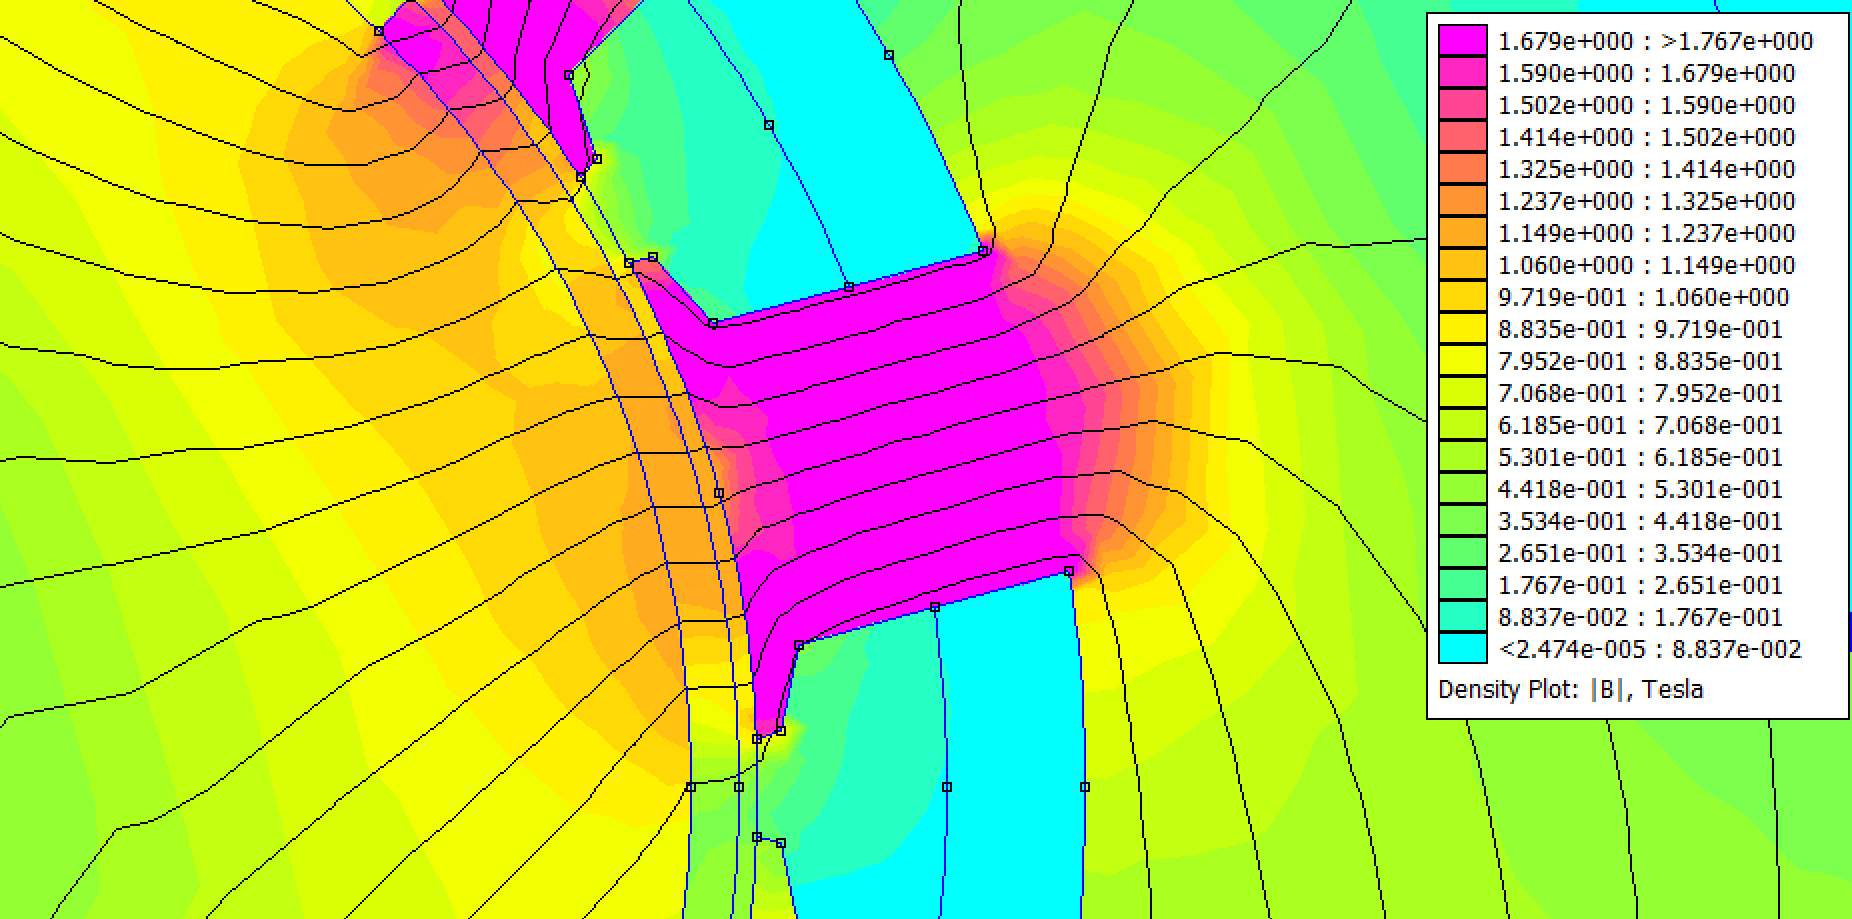

- Field in the stator tooth, $\hat{B}_T = 1.7~T$.

- Field in the stator yoke, $\hat{B}_y = 0.8~T$.

I suspect the reason for the difference is because of the adjustment of the stator yoke thickness. My intuition is that if I decrease the stator yoke thickness and increase the tooth length, the readings should get closer. That would increase the stator tooth width, which would decrease the field in the tooth.

Magnetic Loading:

- Magnetic loading, $\hat{B}_{\delta}=0.984~T$

This one is harder to tell. My airgap length choice may be too small, which may lead to high field gradients and consequently a higher magnetic field in the airgap. I used 360 sample points, a larger number of sample points may also lead to a value closer to my assumption.

MATLAB Code Results:

openfemm;
opendocument('Test.fem');
mi_setgrid(1,'polar');

% Set zero current
mi_setcurrent('U', 0);
mi_setcurrent('V', 0);
mi_setcurrent('W', 0);

% Analyze and load solution
mi_analyze(1);
mi_loadsolution;

% Sample radial airgap field
L = 360;
rSample = r; % mm
dAlpha_deg = 360 / L;
alpha_deg = (0:L-1) * dAlpha_deg;

Br = zeros(1, L);
for i = 1:L
    x = rSample * cosd(alpha_deg(i));
    y = rSample * sind(alpha_deg(i));
    B = mo_getb(x, y);
    Br(i) = B(1)*cosd(alpha_deg(i)) + B(2)*sind(alpha_deg(i));
end

mo_close;
alpha_rad = deg2rad(alpha_deg);
Y = fft(Br);
P2 = abs(Y/L);
BrHarmonics = 2*P2(1:L/2+1);
n = 0:L/2;

% Plot spectrum 
figure;
stem(n, BrHarmonics, 'filled', 'MarkerSize', 3);
xlabel('Harmonic Index $n$', 'Interpreter','latex','FontSize',10);
ylabel('$\hat{B}_{\delta,n}$ [T]', 'Interpreter','latex','FontSize',10);
title('Airgap Field Harmonic Spectrum','Interpreter','latex','FontSize',12);
grid on;
fprintf('\nThe field contains the following harmonics:\n');
fprintf(' n | B_r,n [T]\n');
for i = 1:length(n)
    if BrHarmonics(i) > 0.01
        fprintf('%2.0f | %1.3f\n', n(i), BrHarmonics(i));
    end
end

% Magnetic Loading
magneticLoading = BrHarmonics(3);  % n=2 -> index = 3 (since n starts at 0)
fprintf('\nMagnetic loading (n=2): %.3f T\n', magneticLoading);

### Question 10

Create a MATLAB script called optimizeMotor.m that uses gamultiobj to optimize your motor design. Use a population size of at least 50. Determine appropriate values for settings.lowestHarmonic and settings.steps.

### Question 11

Run your optimization to find a set of designs that meet your customer’s requirements. Run your optimization for however many generations is takes to find a set of suitable designs to meet your customer’s requirements (I recommend trying 50 or more generations).

Note:

My personal computer crashes if I attempt to run for a large number of generations. So with the help of a few of my colleagues, I have decided to run the optimization for 5 generations with a population of 50 and save my final population, scores and pareto front for later use. I then repeated this 5 times to get the results. This is far from the 50 generations recommended, but it does produce motors with dimensions that fulfill the requirements of the customer.

### Question 12

Create a document analyzing your final generation of candidate designs. This should be a typed document with the following plots/information.

#### Part (a)

Create a 3D plot of your objectives. X axis: efficiency, Y axis: torque ripple, Z axis: cost

load par_front_gen1.mat
load population1.mat
load scores_gen1.mat
dotsize = 10;
scatter3(-[scores(:,2)],[scores(:,3)],[scores(:,1)] , 'filled')
xlabel('$O_1$: Efficiency [\%]', 'Interpreter','latex','FontSize',8,...
             'FontName','TimesNewRoman');
ylabel('$O_2$: Torque Ripple [Unitless]', 'Interpreter','latex','FontSize',8,...
             'FontName','TimesNewRoman');
zlabel('$O_3$: Cost [\$]', 'Interpreter','latex','FontSize',8,...
             'FontName','TimesNewRoman');
set(gca,'FontName','TimesNewRoman','FontSize',8, 'color', 'none');

#### Part (b)

Create a 2D plot of your objectives. X axis: efficiency, Y axis: torque ripple, Marker color: cost

#### Part (c)

Create a table that compares the following designs. Each column of the table should correspond to one of the designs listed below. The rows of the table should consist of each of the free variables, each of the objectives, the magnetic loading (calculated using an FFT from a FEMM solve), and the electric loading. This table needs to be professionally formatted and use appropriate column/row labels and units.

1. “Lowest Cost Design” –The lowest cost design that meets the customer’s requirements (efficiency and torque ripple)

2. “Most Efficient Design” –The most efficient design that meets the torque ripple requirements

3. “Lowest Ripple Design”—The lowest ripple design that meets the efficiency requirements

4. “Recommended Design”— Pick one design that you think will impress your manager the most (best compromise of all objectives).

#### Part (d)

For the design you recommended in part C, provide an image of the machine’s crosssection (this can be a screenshot from FEMM or you can export the DXF file and render it in higher quality with a CAD tool). In three sentences, explain to your manager why you have selected this design.

#### Part (e)

You are trying to convince your company that using optimization techniques will allow the company to create more competitive motors than using analytic design techniques alone. Write a brief paragraph (five sentences or less) explaining the merits of using optimization in the machine design process by comparing the performance of your optimal designs with the analytic design you created in question 5.